# **34754 Autonomous Robots Systems **

### **Week 1 Exercises**

**This series of exercises was conducted by group 4, consisting of: **

Kristian Kjær Bruun, s205032

Jonas Falk Jakobsen, s195450

Harald Ledertoug Lissay, s204436

Jonas Poulsen, s194243

**Please notice that some functions are in appendix A at the bottom.**

**OBS: **Please note that this file might contain direct excerpts from the different exercise files for description of the different problems.

# Exercise 1: Exercise Facilities and Simulator

## 1.2 Introduction to the computer environment

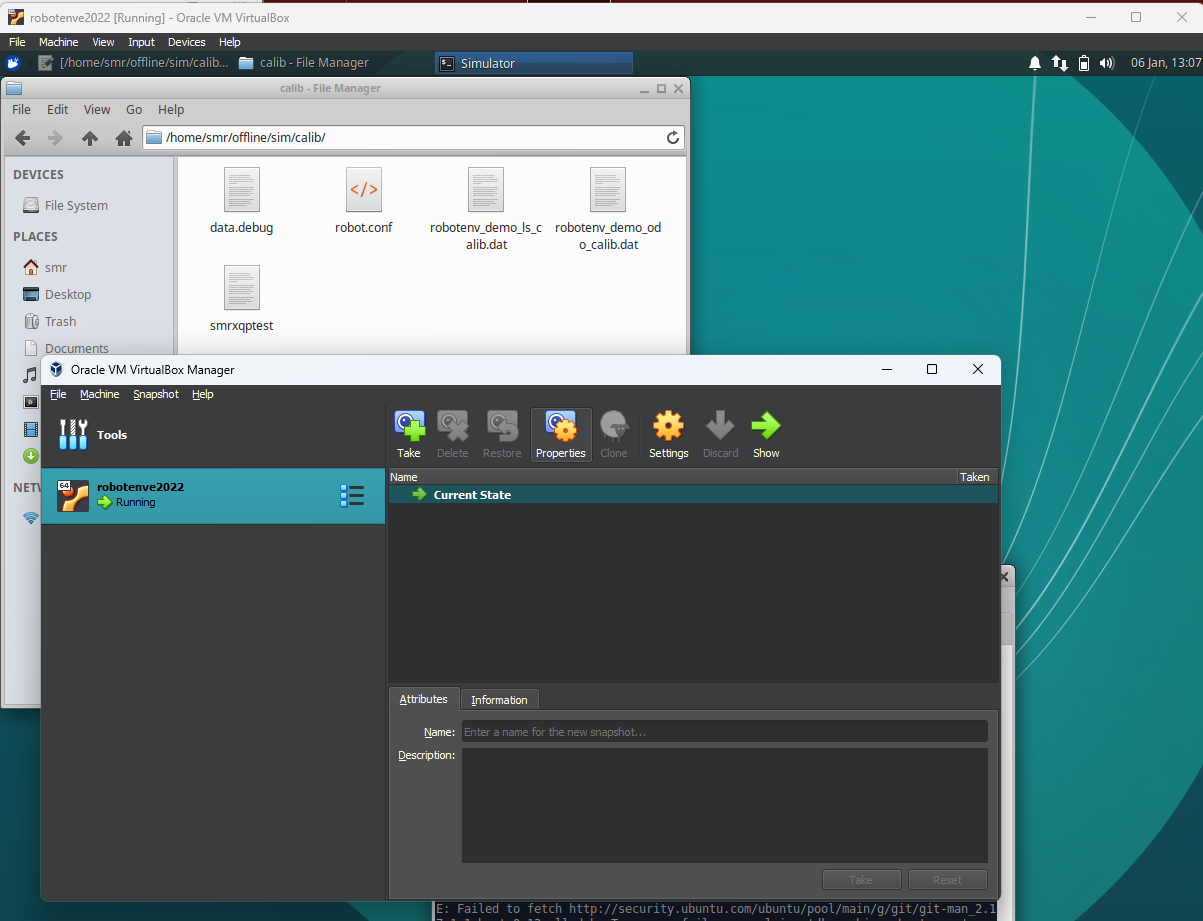

The environment works.

## 1.3 Introduction to the simulator and SMR-CL

### 1.3.1 - 1.3.4 Start terminals and initial commands

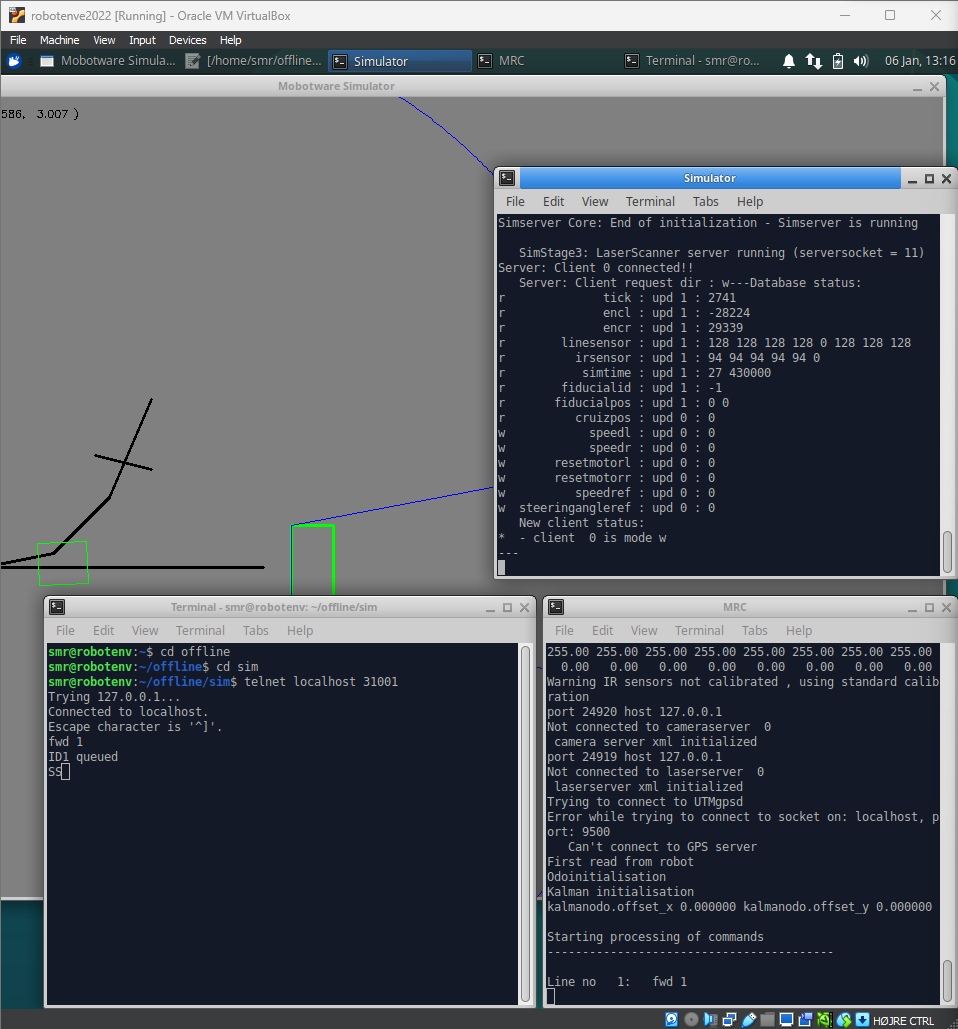

### 1.3.5 Driving using SMR-CL scripts

In the following we made the different scripts performing various tasks. 

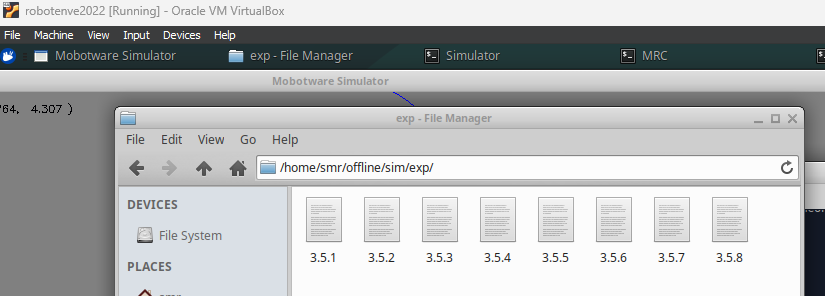

#### 1.3.5.1

#### 1.3.5.2

#### 1.3.5.3

#### 1.3.5.4

#### 1.3.5.5

#### 1.3.5.6

#### 1.3.5.7

#### 1.3.5.8

# Exercise 2: Kinematics and Odometry

## 2.1 Objective

The objective of this exercise is to give an introdution to kinematics and odometry for mobile robots.

## 2.2 Material and preparation

The material for this exercise is found in "Where am I", section 1 and 5 and UMB-mark chapter 6.

## 2.3 Calculation of vehichle position

The aim is to calculate and cntrol where we are and where we are going. Kinematics is the study of motion without regard to the force which cause it. Within kinematics one studies the position and accecleration etc. First we calculate where we are based on encoder measurements. This is called the odometry model. 

The **incremntal displacement **of each **wheel**


$$\Delta U_{L/R}(i)=c_mN_{L/R}(i)$$


where $c_m=\frac{\pi D}{nC}$, where $D$ is the diameter of the wheels, $n$ is the gear ratio between the encoder and wheel and $C$ is the number of pulses per revolution. 

**Center point displacement **is given by 

$\Delta U(i)=\frac{\Delta U_r +\Delta U_L}{2}$.

The **incremntal change in orientation **is given by


$$\Delta \theta(i)=\frac{\Delta U_R-\Delta U_L}{b}$$


Where $b$ is the wheel distance (distance between the two wheels).

The new pose of the robot is therefore


$$x(i)=x(i-1)+\Delta U(i) \cdot \cos(\theta(i))$$



$$y(i)=y(i-1)+\Delta U(i) \cdot \sin(\theta(i))$$



$$\theta (i) = \theta(i-1)+\Delta \theta (i)$$


D=0.065; % Diameter of the wheels
N=1;     % Gear ration between encoder and wheel
C=2000;  % Number of pulses per revolution
b=0.26;  % Distance between wheels given in meters
L=1;     % Side lengt

### 2.3.1 Matlab script to calculate $E_b$ and $E_d$

Make a matlab script that takes the errors from a clockwise experiment $X_{cw}$ and $Y_{cw}$ and the errors from a counter clockwise experiment $X_{ccw}$ and $Y_{ccw}$ and the side length $L$ and the nominal width as inputs and calculate $E_d$ and $E_b$ as output.

The formula for $\beta$ is


$$\beta=\frac{x_{c., g.,cw}-x_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


and for the y-coordinate


$$\beta=\frac{y_{c., g.,cw}+y_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


The radius of the curvature $R$ of the curved path can be found using simple geometric relations. The radius is given as:


$$R=\frac{L/2}{\sin(\beta/2)}$$


We can at last determine the ration between the two wheel diameters that caused the robot to travel on a curved, instead of a straight path (see fig. 6.4):


$$E_d=\frac{D_R}{D_L}=\frac{R+b/2}{R-b/2}$$


% First get the beta values
[beta_x, beta_y] = calcBeta(0.2,0.12, 0.2, -0.12, L)

beta_x = -0.0200

beta_y = -0.0200


% Let's mean the values to make one beta value
beta=(beta_x+beta_y)/2

beta = -0.0200


% Calculate the radius
R = calcR(L, beta)

R = -50.0008


% At last we can calucate Ed
Ed = (R+b/2)/(R-b/2)

Ed = 0.9948

Let's calculate the wheelbase error $E_b$. For this we need to calculate $\alpha$ which is given by 


$$\alpha=\frac{x_{c., g.,cw}+x_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


and for the y-coordinate


$$\alpha=\frac{y_{c., g.,cw}-y_{c., g.,ccw}}{-4L}\cdot \frac{180}{\pi}
$$


We then have the equation


$$E_b=\frac{90^\circ}{90^\circ - \alpha}$$


% First get the beta values
[alpha_x, alpha_y] = calcAlpha(0.2,0.12, 0.2, -0.12, L)

alpha_x = -0.0800

alpha_y = -0.0800


% Let's mean the values to make one beta value
alpha=(alpha_x+alpha_y)/2

alpha = -0.0800

Eb = (90/(90-alpha*(180/pi)))

Eb = 0.9515

### 2.3.2 UMB-mark in the simulator

Now let's try with som values from the simulator. 

% Observed values
L=2;
x_cw = 0.266;
y_cw = 2.217-2;
x_ccw = 0.266;
y_ccw = 1.783-2;

Find $E_d$:

[beta_x, beta_y] = calcBeta(x_cw, x_ccw, y_cw, y_ccw, L);
beta=(beta_x+beta_y)/2;
R = calcR(L, beta);
Ed = (R+b/2)/(R-b/2)

Ed = 1

And let's find $E_b$:

% First get the beta values
[alpha_x, alpha_y] = calcAlpha(x_cw, x_ccw, y_cw, y_ccw, L)

alpha_x = -0.0665

alpha_y = -0.0543


% Let's mean the values to make one beta value
alpha=(alpha_x+alpha_y)/2

alpha = -0.0604

Eb = (90/(90-alpha*(180/pi)))

Eb = 0.9630

The new wheel base value $b$

b_actual = Eb*b

b_actual = 0.2504

We insert the new $E_d=1$ (same) and the new wheel base distance $b_{actual}=0.2504$, which results in much better results:

- Clockwise:     (-0.021,1.974,0.016)

- Counter CW: (-0.021,2.026,-0.016)

compared to the original positions (before calibration)

- Clockwise:     (0.266, 2.217,-0.258)

- Counter CW: (0.266,1.783,0.258)

We also tried using the integrated calibration function, which resulted in the following values for callibration:

- Wheel base: 0.250376 

- $E_d$: 0.999999

Which is quite close to what we caluclated. The results are very similar:

- Clockwise:     (-0.022,1.974,0.018)

- Counter CW: (-0.022,2.026,-0.017)

# Exercise 4: Robot programming in C

## 4.2 Robot hardware interface RHD

We modified the square program so that the SMR turns around the center of the vehicle instead of one wheel. This was done by changing:

## 4.3 Basic Motion Control and Odometry

We will in the following change the square.c script through several tasks.

### 4.3.1 Logging the square program

Two function were made for logging:

The sm_saveArray() function is called through the update_motcon() function, and the writeToFile() function is called at last (just before exit). 

**Answers to questions:**

*Why should we use a statically allocated array? *

A static array is used because we can find the size of the array, because of that we do not need to be responsible for allocating the memory, and the program is faster. 

*Think about what happens if the end of the array is reached. *

If the end of the arrays is reached and more data is added to the array, it gives undefined behaviour.

*Run the square program with logging and make a matlab plot of the motorspeeds versus time.*

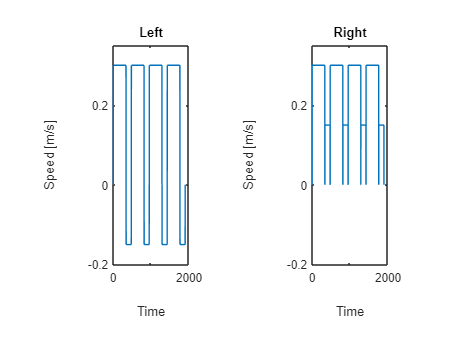

lrspeed=importdata('logs/log.dat');
figure(1);
subplot(1,2,1)
plot(lrspeed(1:end, 2))
title("Left")
xlabel("Time")
ylabel("Speed [m/s]")
ylim([-0.2, 0.35])


subplot(1,2,2)
plot(lrspeed(1:end, 3))
title("Right")
xlabel("Time")
ylabel("Speed [m/s]")
ylim([-0.2, 0.35])

### 4.3.2 Implement odometry

We have to find x, y and theta in the square program.

First, we added some new variables to the odotype struct:

Next we changed the update_odo function, caluclating the different odometry using the formulas from the "Where am I" book, page 20:

and at last we wish to update the reset_odo function to reset our new variables by adding the line:

We updated the logging function from before, containing the new variables, and ran the clockwise and counter-clockwise square. We wish to sanity check our results by ploting the individual positions over time:

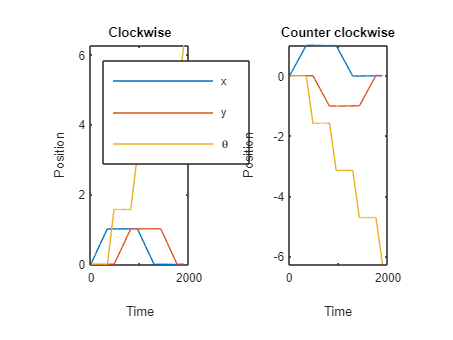

odo_cw=importdata('logs/ex_4_3_2_cw.dat');
figure(2);
subplot(1,2,1)
plot(odo_cw(1:end,4:6))
legend(["x", "y", "\theta"], location='northwest')
title("Clockwise")
xlabel("Time")
ylabel("Position")

odo_ccw=importdata('logs/ex_4_3_2_ccw.dat');
subplot(1,2,2)
plot(odo_ccw(1:end,4:6))
title("Counter clockwise")
xlabel("Time")
ylabel("Position")

Below we plot the xy-plot for both clockwise and counter clockwise:

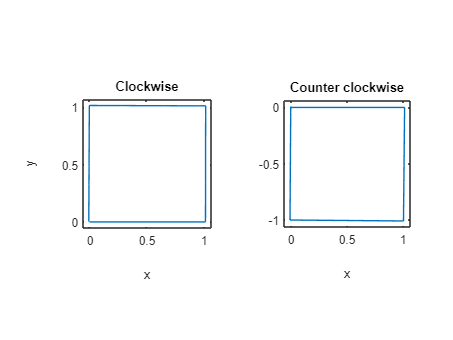

odo_cw=importdata('logs/ex_4_3_2_cw.dat');
odo_ccw=importdata('logs/ex_4_3_2_ccw.dat');

xyplot({odo_cw, odo_ccw}, 0.05, {'Clockwise', 'Counter clockwise'})

### 4.3.3 Modify the square program and plot x, y and $\theta$

To make the SMR move 2m and stop at different speeds, we changed the case of moving foward so it just ends after moving forward, and moves 2 meters with different velocities. We then changed the speed by simply commenting out the different lines:

Below we plotted the x, y and $\theta$ value over time:

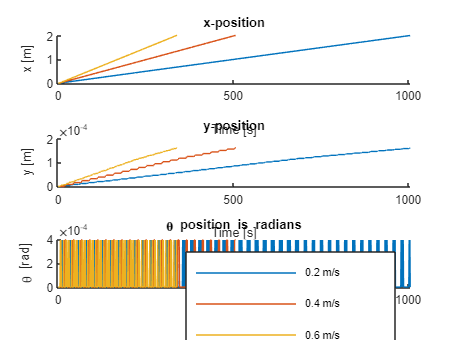

odo02=importdata('logs/ex_4_3_3_02.dat');
odo04=importdata('logs/ex_4_3_3_04.dat');
odo06=importdata('logs/ex_4_3_3_06.dat');

exe4_plot(odo02, odo04, odo06)

### 4.3.4 Limit the acceleration

As above, we wish in the end to plot the x, y and $\theta$. However, this time we limit the acceleration to $0.5\frac{m}{s^2}$. This is done by inserting the following statements in the update_motcon function insted of the old motorspeed configuaration:

where the tick accelleration is defined as the frequency over the acceleration:

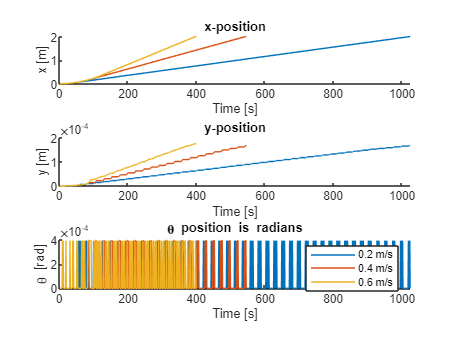

odo02=importdata('logs/ex_4_3_4_02.dat');
odo04=importdata('logs/ex_4_3_4_04.dat');
odo06=importdata('logs/ex_4_3_4_06.dat');

exe4_plot(odo02, odo04, odo06)

### 4.3.5 Deceleration

As before,we wish to plot the x, y and $\theta$ value for going 2 meters, however this time we limit the decelleration of the SMR using the formula $V_{max}=\sqrt{2a_{max}d}$. This was done by measuring the distance, and using the formula given in the update_motcon function:

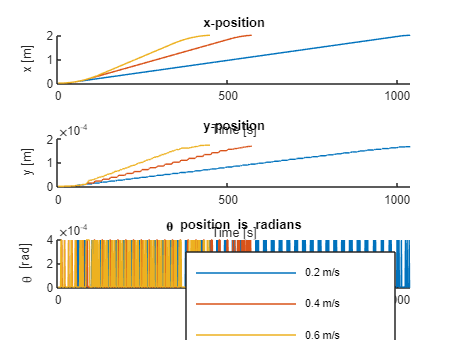

odo02=importdata('logs/ex_4_3_5_02.dat');
odo04=importdata('logs/ex_4_3_5_04.dat');
odo06=importdata('logs/ex_4_3_5_06.dat');

exe4_plot(odo02, odo04, odo06)

### 4.3.6 Adding acceleration and deceleration to the turn

We made a series of code changes to the mot_turn function:

Which resulted in the following x, y and $\theta$ values when doing the clockwise and counter clockwise square:

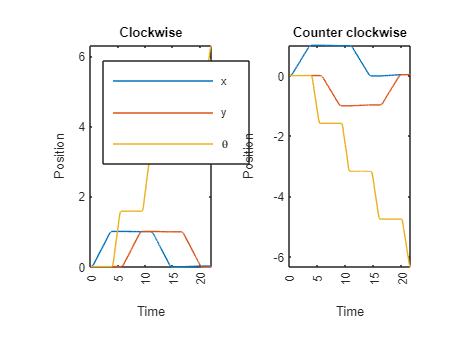

odo_cw=importdata('logs/ex_4_3_6_cw.dat');
figure(4);
subplot(1,2,1)
plot(odo_cw(1:end,4:6))
title("Clockwise")
xlabel("Time")
ylabel("Position")
legend(["x", "y", "\theta"], Location='northwest')
xt = get(gca, 'XTick');
set(gca, 'XTick',xt, 'XTickLabel',xt/100)

odo_ccw=importdata('logs/ex_4_3_6_ccw.dat');
subplot(1,2,2)
plot(odo_ccw(1:end,4:6))
title("Counter clockwise")
xlabel("Time")
ylabel("Position")
xt = get(gca, 'XTick');
set(gca, 'XTick',xt, 'XTickLabel',xt/100)

We find that the corners of the curves has been rounded, which make a lot of sense as the SMR acceleration and deceleration has been applied both before,under and after the turns.

# 5. Laserscanner

## 5.3 Running the simulator with the Square Program

**Key information: **

- The angular resolution is 0.36 degrees

- The scanfield is 180 degrees

- Lasers are seperated into 9 zones (20 degrees each)

### 5.3.1 Placing the SMR 45 cm close to the wall

First we moved the SMR towards the wall, so the distance between wall and laser is 45 cm. It can be seen above that only sensor l4 (in the middle) registers an object, which is the distance 2.44m. 

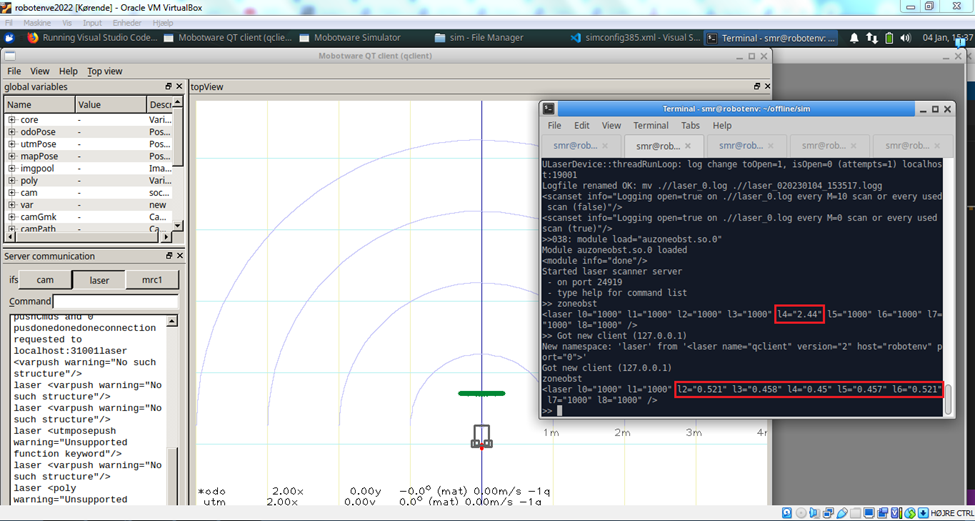Thus the command drives 2 meters forward and more of the sensors (l2,l3,l4,l5,l6) detect the object. l4 is changed to 0.45 m from the object after driving 2 meters forward as expected.

**Theoretical Calculations**

Knowing the distance of 45 cm between the SMR and obstacle, the height of the obstacle is 60 cm and that the SMR is perpendicular on the obstacle, then a right triangle can be constructed with the lengths 30 cm and 45 cm. Trigonometry can be used to find the maximum sensor angle as shown below:

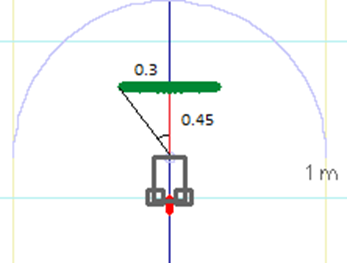


$$\theta = \tan^{-1}\left(\frac{0.3}{0.45}\right) \cdot \frac{180}{\pi} = 33.69 ^\circ$$


Since there is an unequal number of sensors (9), the middle sensor l4 must have a detection range of -10 degrees to 10 degrees, and then adjacent sensors must have detection ranges of 10 to 30 degrees and 30 to 50 degrees in each direction, which all include the 33.69 degrees maximum. That makes a total of 5 sensors in the middle, which would be l2, l3, l4, l5, and l6, which is the same as the results of the simulation.

*Calculating the thoretical distance *

Let's calculate the distance for l3 and l2 and see how they compare with the measured distance. We name the hypotenuse *c, *and the known length $a$ and the know angle $A$. We know that the l3 laser measure between 10 and 30 degrees (to the left). Assuming the wall is straigth, we calculate these two distance and find the mean between those:


$$c_{\textrm{right}} =\frac{b}{\cos {\left(A\right)}}=\frac{0\ldotp 45}{\cos {\left({10}^{\circ } \right)}}=0\ldotp 4569$$



$$c_{\textrm{left}} =\frac{b}{\cos {\left(A\right)}}=\frac{0\ldotp 45}{\cos {\left({30}^{\circ } \right)}}=0\ldotp 5196$$


which results in an average distance of 0.4883. However, comparing this with the measured distances, it seems more likely that it returns the lowes value in each zone. Therefore, the theoretical distance for l3 matches $c_{right}$ and l2 $c_{left}$. The measured distances are quite close the the calculated ones. 

### 5.3.2 Turning the SMR away from the wall

SMR looking parallel to the wall with the wall to the left or right and a distance of 45 cm from the laser to the wall. The SMR was rotated 90 degrees in each direction by using the commands:

- mrc1 turn 90   //turn left

- mrc1 turn -90  //turn right

The results of the rotations can be seen below:

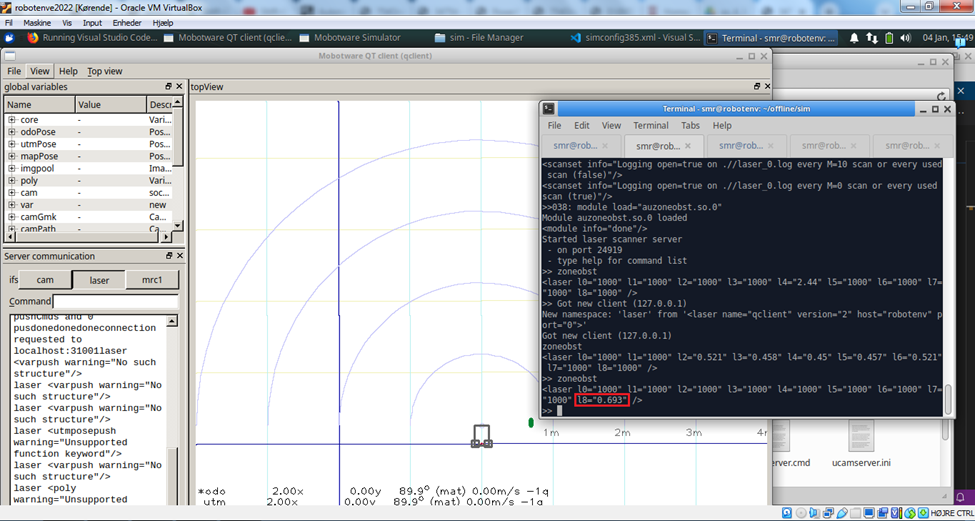

When the SMR turned 90 degrees to the left, only the closest sensor l8 could register the obstacle.

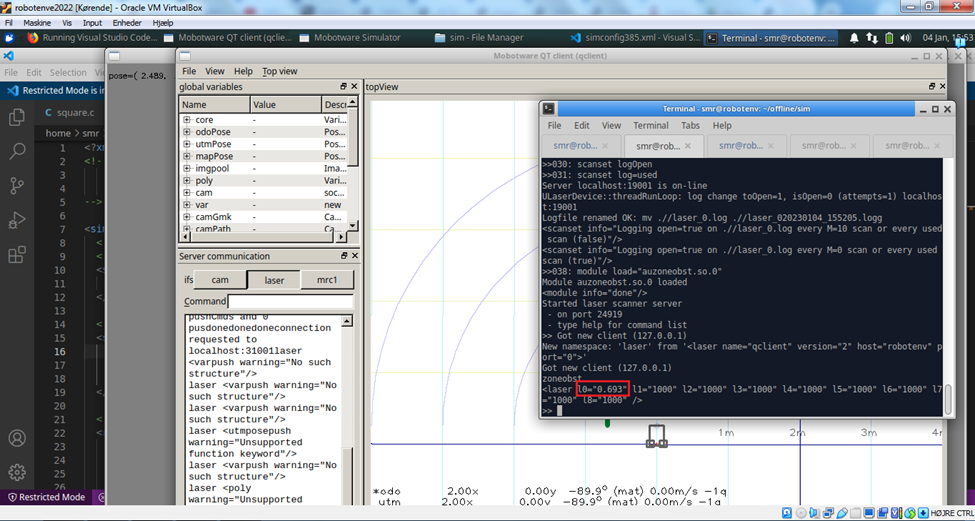

When the SMR turned 90 degrees to the right, only the closest sensor l0 could register the obstacle.

**Theoretical  calculations**

Knowing that the SMR spins around its own center between the back wheels, and that the sensors are in the front of the SMR, the sensors are moved 26 cm in the y-direction when the SMR is turned 90 degrees in left or right direction. Subtracting the movement from the 30 cm a new right angle can be constructed and a maximum angle can be calculated as before.


$$\theta = \tan^{-1}\left(\frac{0.04}{0.45+0.26}\right) \cdot \frac{180}{\pi} = 3.2245 ^\circ$$


This is illustrated below:

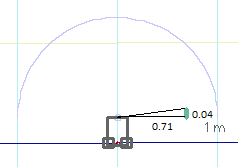

Subtracting this angle from 90 degrees due to having 0 degrees in the middle: 


$$90-3.22 = 86.78^\circ$$


Since the sensor most to the sides have ranges of 70-90 degrees, only the sensor furthest to the sides contain this angle, thus only this sensor should be able to detect the obstacle. This also fits the results of the simulations, since only one sensor detects the obstacle when the SMR is parallel to the obstacle.

We know that the shortest distance from the laser to the wall is 71 cm which about 2 cm different from the measure values.

## 5.4: Logging the laser values in the C program

We changed the the suggested line as told so and modified the logging function from earlier to contain the values from the 9 lasers. A part of the resulting log is showed below:

laserlog = importdata("logs\laserlog.dat");
disp(laserlog(445:455, 1:end))

   1.0e+03 *

    1.0000    1.0000    0.0015    0.0014    0.0015    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.0015    0.0015    1.0000    1.0000    1.0000    1.

# Exercise 6: Calibration

### 6.2.1 Calibration of linesensor

*Write a SMR-CL script that logs at least 100 linesensor measurements at the starting position an then moves 0.3 meters forward and takes another 100 measurements.*

The log-file can be seen below, which shows the raw data of the line sensor variables ranging in a grayscale range from 0-255. Below shows that the SMR starts at the black line (0 values) then enters gray region (128) and the white lines (255 values).

data = importdata("logs/ex_6_1.dat");
data = data./255;

% Just showing a few values
disp(data(200:210, 1:5))

    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    0.5020    0.5020    0.5020    0.5020    0.5020
    0.5020    0.5020    0.5020    0.5020    0.5020
    0.5020    0.5020    0.5020    0.5020    0.5020
    0.5020    0.5020    0.5020    0.5020    0.5020



### 6.2.2 Calibration of IR-distance sensors

The SMR-CL script has been implemented: 

and the measurements were logged and are loaded in below. 

data = importdata("logs/6_2_alt_log.dat");

%data = data(1:end, 1:5) % We drop the last row 
% 1 is left 
% 2 is left front
% 3 is middle
% 4 is right front
% 5 is right

data(data(:, 7)== 0, :)= []; % Drop rows where SMR is moving
data = data(:, 1:6); % Don't need that move/not-move column anymore

Lets group by length

% Inspired by the answer from Andrei Boborv: 
% https://www.mathworks.com/matlabcentral/answers/352178-group-an-array-according-a-condition
g = findgroups(data(:,6)); 
[ii,jj] = ndgrid(g,1:size(data,2));
data = accumarray([ii(:),jj(:)],data(:),[],@mean);

Extract the xvalues:

xdata = data(:, 6)*100;
% We can fetch the y data from column 2, 3, 4

We know that the output of the sensor is given as


$$ir_{out}=K_1 \cdot \arctan\left(\frac{K_2}{dist}\right)+K_3$$


- $K_1$ is the scaling factor, limiting the output to 255

- $K_2$ is the distance between the source and the PSD. 

- $K_3$ is an offset

- $dist$ is the distance to the object

However, the above can be simplified


$$ir_{out}=\frac{K_a}{dist}+K_b$$


Which means the distance can be calculated as


$$dist=\frac{K_a}{ir_{out}-K_b}$$


where $K_a$ and $K_b$ has to be calibrated. Let's estimate these two values:

figure;
hold on
labels = ["Left front", "Middle front", "Right front"];
linestyle = ["-.", "--", ":"];
for i = 2:4
    fitted = lsqcurvefit(@irdist, [16,10], xdata, data(:, i));
    f=@(x) (fitted(1)./x+fitted(2));
    x = 10:0.1:100;
    plot(x, f(x), "DisplayName", labels(i-1), LineStyle=linestyle(i-1));
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

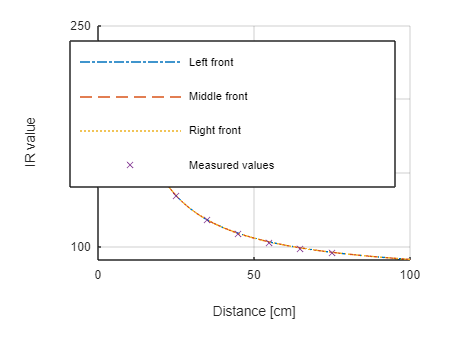


% We just plot for one as they are the same
scatter(xdata, data(:,2), 'x', "DisplayName","Measured values") 
hold off
grid on
xlabel("Distance [cm]")
ylabel("IR value")
legend show


ka = fitted(1)

ka = 1.4418e+03

kb = fitted(2)

kb = 76.8319

# Exercise 7: Control

## 7.2 Direction control

We recall that we have to angular values

- $\theta_{ref}$ is the angle that we wish to achieve

- $\theta_{odo}$ is the angle that we measure by looking at the difference of speed in each wheel

We wish to implement an angular proportional controller using the following formular:


$$\Delta V=K\cdot(\theta_{ref}-\theta_{odo})$$


Which we can calculate and utilize the difference in the update_motcon function by:

The reason why we devide it with the proportional value $\Delta V$ with 2 is because we apply the change of speed on both wheels at the same time. 

Furthermore we allow that velocity of each wheel can be changed with this $\Delta V$ value by changing the acceleration constraints for each vehicle:

Our proportional constant $K$ will be set to 0.04 as we initially think that the change in velocity shouldn't be higher that 0.06 m/s and that the angular difference won't be higher than $\pm 20^\circ$:


$$K=\frac{\Delta V}{\theta_{ref}-\theta_{odo}}=\frac{0.06 \text{m/s}}{20^\circ}=0.1714$$


Below we have plotted the x and y  positions:

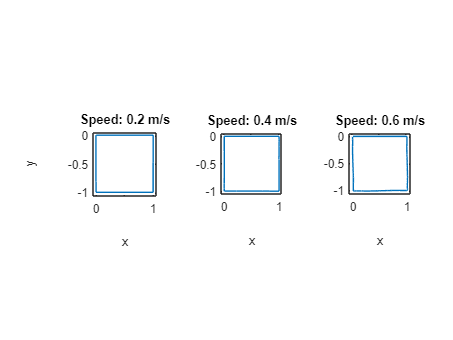

odo_02=importdata('logs/71_02.dat');
odo_04=importdata('logs/71_04.dat');
odo_06=importdata('logs/71_06.dat');

labels = {'Speed: 0.2 m/s', 'Speed: 0.4 m/s', 'Speed: 0.6 m/s'}
xyplot({odo_02, odo_04, odo_06}, 0.05, labels)

And lets plot the values over time

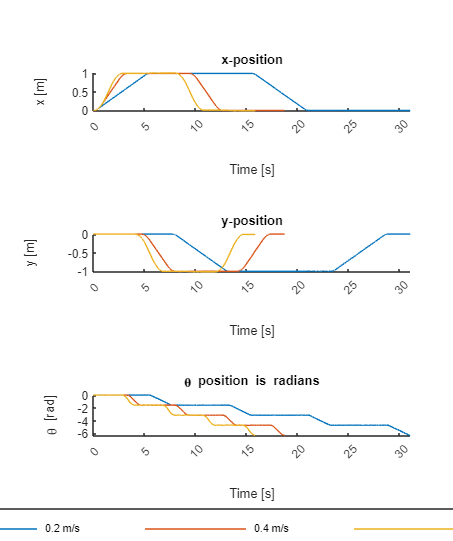

exe4_plot(odo_02, odo_04, odo_06)

## 7.3 Line following controller

# Appendix A: Functions 

function [beta_x, beta_y] = calcBeta(x_cw,x_ccw, y_cw, y_ccw, L)
    beta_x = ((x_cw-x_ccw)/(-4*L));
    beta_y = ((y_cw+y_ccw)/(-4*L));
end

function [alpha_x, alpha_y] = calcAlpha(x_cw,x_ccw, y_cw, y_ccw, L)
    alpha_x = ((x_cw+x_ccw)/(-4*L));
    alpha_y = ((y_cw-y_ccw)/(-4*L));
end

function [R] = calcR(L, beta)
    R=(L/2)/sin((beta+realmin)/2);
end

### **XY plot function**

function [] = xyplot(data, spacing, titles)
    clf();
    num_plots = length(data);
    figure;
    for i= 1:num_plots
        odo = data{i};
        subplot(1,num_plots,i)
        plot(odo(1:end,4), odo(1:end,5))
        title(titles{i})
        if i == 1, ylabel("y"), end
        xlabel("x")
        axis equal;
        xlim([min(odo(1:end,4))-spacing, max(odo(1:end,4))+spacing])
        ylim([min(odo(1:end,5))-spacing, max(odo(1:end,5))+spacing])
    end
end

### Plot function for exercise 4

function [] = exe4_plot(log1, log2, log3)    
    max_ticks = (max([length(log1), length(log2), length(log3)]));
    clf();
    
    figure;
    subplot(3,1,1)
    hold on
    plot(log1(1:end,4))
    plot(log2(1:end,4))
    plot(log3(1:end,4))
    hold off
    title("x-position")
    xlabel("Time [s]")
    ylabel("x [m]")
    xlim([0, max_ticks])
    xt = get(gca, 'XTick');
    set(gca, 'XTick',xt, 'XTickLabel',xt/100)
    
    
    subplot(3,1,2)
    hold on
    plot(log1(1:end,5))
    plot(log2(1:end,5))
    plot(log3(1:end,5))
    hold off
    title("y-position")
    xlabel("Time [s]")
    ylabel("y [m]")
    xlim([0, max_ticks])
    xt = get(gca, 'XTick');
    set(gca, 'XTick',xt, 'XTickLabel',xt/100)
    
    
    subplot(3,1,3)
    hold on
    plot(log1(1:end,6), "DisplayName","0.2 m/s")
    plot(log2(1:end,6), "DisplayName","0.4 m/s")
    plot(log3(1:end,6), "DisplayName","0.6 m/s")
    hold off
    title("\theta position is radians")
    xlabel("Time [s]")
    ylabel("\theta [rad]")
    xlim([0, max_ticks])
    xt = get(gca, 'XTick');
    set(gca, 'XTick',xt, 'XTickLabel',xt/100)
    

    fig = gcf;
    fig.Position(4) = fig.Position(4) + 250;
    % add legend
    Lgnd = legend('show', 'NumColumns',3);
    Lgnd.Position(1) = 0.3;
    Lgnd.Position(2) = 0.01;
end

### Exercise 6.2

function irout = irdist(k,d)
    % d is distances in meter 
    % Note that k = [ka kb]
    irout = k(1)./d+k(2);
end